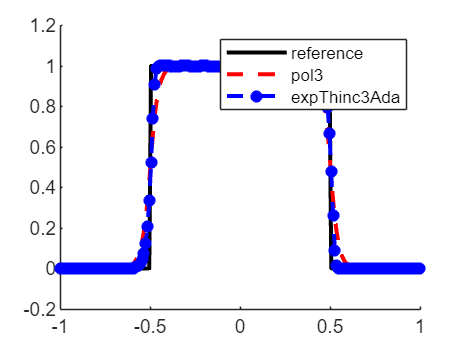

clc; clear; close all;
global config

% config = 1;
% [solutionWeno5, x_grid, solution0] = getSolution();

config = 2;
[solutionPol3, x_grid, solution0] = getSolution();

% config = 3;
% [solutionExp3, x_grid, solution0] = getSolution();

% config = 4;
% [solutionExp3TVB, x_grid, solution0] = getSolution();

global lambdaVec
lambdaVec = zeros(1, 206);

% config = 5;
% [solutionExp3New, x_grid, solution0] = getSolution();

config = 6;
[solutionThinc3New, x_grid, solution0] = getSolution();


figure
hold on
plot(x_grid, solution0, 'k', 'linewidth', 2,'DisplayName', 'reference')
% plot(x_grid, solutionWeno5, '--', 'linewidth', 2, 'DisplayName', 'WENO5')
plot(x_grid, solutionPol3, '--r', 'linewidth', 2, 'DisplayName', 'pol3')
% plot(x_grid, solutionExp3, '--', 'linewidth', 2, 'DisplayName', 'EXP3')
% plot(x_grid, solutionExp3TVB, '--', 'linewidth', 2, 'DisplayName', 'EXP3TVB')
% plot(x_grid, solutionExp3New, '--b', 'linewidth', 2, 'DisplayName', 'exp3Ada')
plot(x_grid, solutionThinc3New, '--b*', 'linewidth', 2, 'DisplayName', 'expThinc3Ada')
legend
hold off

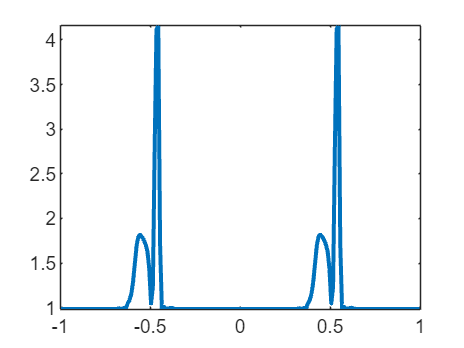


plot(x_grid, lambdaVec(4:203), 'LineWidth', 2)

function [solution, x_grid, solution0] = getSolution()
% 定义问题参数
f = @(x) x;                    % 通量函数
g = @(x) 1;                    % 通量导数
domain_left = -1;               % 计算区间左端点
domain_right = 1;              % 计算区间右端点
final_time = 2;              % 终止时间

% 网格参数设置
time_step = 1e-3;                        % 时间步长
num_time_steps = final_time / time_step; % 迭代次数

mesh_points = 200;
space_step = (domain_right - domain_left) / mesh_points;

% 初始化空间网格和解向量
x_grid = domain_left:space_step:domain_right;
solution = zeros(1, mesh_points);

% 计算初始值
for j = 1:mesh_points
    solution(j) = integral(@(x) initial_condition1(x), x_grid(j), x_grid(j+1)) / space_step;
end
solution0 = solution;

% 时间推进（三阶Runge-Kutta方法）
for t = 2:num_time_steps+1
    % RK3 第一步
    k1 = solution + time_step * getL(solution, f, g, space_step);

    % RK3 第二步
    k2 = 3/4 * solution + 1/4 * k1 + ...
        1/4 * time_step * getL(k1, f, g, space_step);

    % RK3 第三步
    solution = 1/3 * solution + 2/3 * k2 + ...
        2/3 * time_step * getL(k2, f, g, space_step);
end
x_grid=0.5*(x_grid(1:end-1)+x_grid(2:end));
end

function u = initial_condition1(x)
u = zeros(size(x));
index = (x >= -0.5 & x <= 0.5);
u(index) = 1;
end

function u = initial_condition2(x)
% Jiang, G.-S., & Shu, C.-W. (1996).
% Efficient Implementation of Weighted ENO Schemes.
% Journal of Computational Physics, 126(1), 202-228.
% https://doi.org/10.1006/jcph.1996.0130

% 参数
z   = -0.7;
delta = 0.005;
beta  = log(2) / (36 * delta^2);
a   = 0.5;
alpha = 10;

% 定义 G 和 F
G = @(x, beta, z) exp(-beta * (x - z).^2);
F = @(x, alpha, a) sqrt(max(1 - alpha^2 * (x - a).^2, 0));

% 初始化 u
u = zeros(size(x));

% 区间 [-0.8, -0.6]
mask1 = (x >= -0.8 & x <= -0.6);
u(mask1) = 1/6 * ( G(x(mask1), beta, z - delta) ...
    + 4*G(x(mask1), beta, z) ...
    + G(x(mask1), beta, z + delta) );

% 区间 [-0.4, -0.2]
mask2 = (x >= -0.4 & x <= -0.2);
u(mask2) = 1;

% 区间 [0, 0.2]
mask3 = (x >= 0 & x <= 0.2);
u(mask3) = 1 - 10 * abs(x(mask3) - 0.1);

% 区间 [0.4, 0.6]
mask4 = (x >= 0.4 & x <= 0.6);
u(mask4) = 1/6 * ( F(x(mask4), alpha, a - delta) ...
    + 4*F(x(mask4), alpha, a) ...
    + F(x(mask4), alpha, a + delta) );

% 其它区间保持为 0
end




